# AuE-6600 | Dynamic Performance of Vehicles

## Homework 6

**Vehicle Parameters:**

- Mass: 1637 kg

- Yaw inertia: 3326 kg-m^2

- Wheelbase: 2.736 m

- Trackwidth: 1.7 m

- Weight distribution: 60% to front

- Front cornering stiffness: 1500 N/deg per tire (static load)

- Rear cornering stiffness: 1146 N/deg per tire (static load)

- Steering ratio: 15:1 (15 degree at the steering wheel = 1 degree at the front wheel)

- CG height: 2.4 ft

**Maneuver Description:**

In this assignment, you are required to simulate the bicycle model for 2 different maneuvers that are described below. Based on the description, for each maneuver, you should create a vector of inputs for the simulation

- The roadwheel steering angle is the input to your bicycle model. In the first maneuver, provide a step input for this steering angle. The vehicle is first being driven down a straight line at 74 mph for 7 seconds after which the driver holds the handwheel position constant at 45 degrees for 60 seconds. The handwheel position is then returned to 0 degrees and the maneuver is terminated

- The second maneuver is called the “fishhook maneuver” where you need to gradually increase the steering angle. To begin this maneuver, the vehicle is first driven in a straight line at 50mph. The driver must attempt to maintain this speed for 5 seconds. After that, the handwheel position is linearly increased from 0 to 270 degrees at a rate of 14.5 degrees per second. The handwheel position is held constant at 270 degrees for 4 seconds, after which the maneuver is concluded. The handwheel is then returned to 0 as a convenience to the driver.

% Vehicle parameters
m = 1637; % kg
Iz = 3326; % kg-m^2
l = 2.736; % m
w = 1.7; % m
a = 0.4*l;
b = l-a;
C_alpha_F = 1500; % N/deg
C_alpha_F = C_alpha_F*(180/pi); % N/rad
C_alpha_R = 1146; % N/deg
C_alpha_R = C_alpha_R*(180/pi); % N/rad
SR = 15;
h = 2.4; % ft
h = h/3.281; % m
% Maneuver description
% Step maneuver
v_step = 74; % mph
v_step = v_step/2.237; % m/s
u_step = [ones(1,7000)*0 ones(1,60000)*(deg2rad(45)/SR) ones(1,13000)*0];
% Fishhook manuever
v_fishhook = 50; % mph
v_fishhook = v_fishhook/2.237; % m/s
u_fishhook = [ones(1,5000)*0 deg2rad(0:(14.5/1000):270)/SR ones(1,4000)*deg2rad(270)/SR ones(1,7379)*0];

### Problem 1

**Part A:**

Now let’s revisit the HW 5 problem 3, extend the bicycle model developed in HW5 problem 3 to determine the position of the CG as well as the direction of the velocity vector in the world (inertial) coordinate frame. For each maneuver, provide a plot for the trajectory of the vehicle. Clearly indicate the location of CG and the velocity vector, at an interval of 1 second, for the complete maneuver. (2 plots in total)

Assume that the CG is laterally in the middle of the vehicle, i.e., the static load is equally distributed to the left and to the right.

**Part B:**

Now it is time to include the effects of Lateral load transfer on cornering stiffnesses of front and rear axle, perform the simulation. Assume that the roll stiffness distribution is the same as the weight distribution

The relationship between cornering stiffness and normal load is given as:


$$C_{\alpha } =a*F_z +b*F_z^2$$


where, $F_z$ is normal load in N and $C_{\alpha }$ is cornering stiffness in N/deg

The following tabular data can be used to find the coefficients ‘a’ and ‘b’.

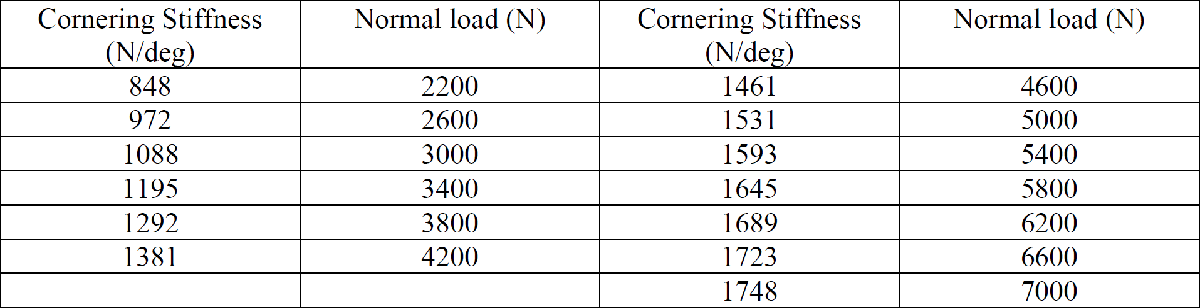

### Solution 1

**Part A**

1. Step Maneuver

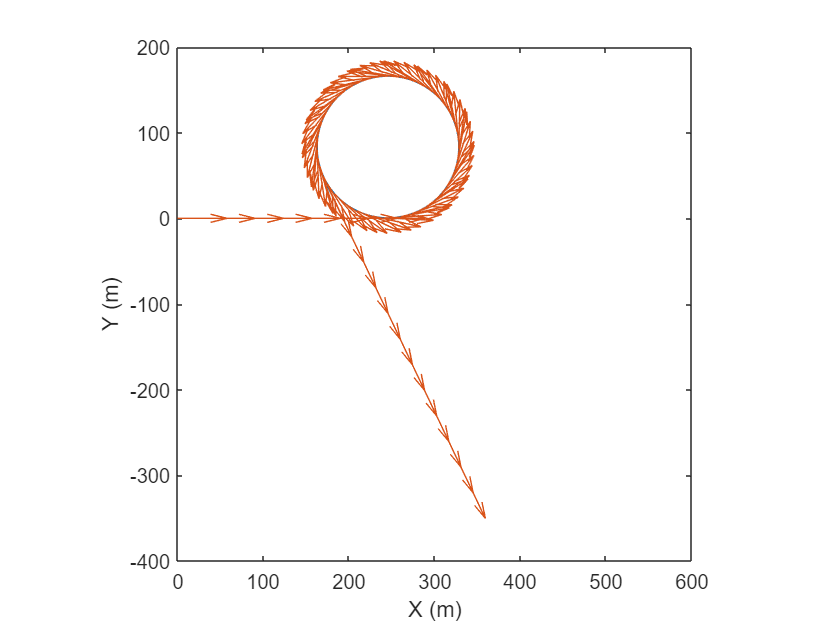

% Single-Track Model
a11 = -((C_alpha_R+C_alpha_F)/(m*v_step));
a12 = (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_step^2))-1;
a21 = ((C_alpha_R*b)-(C_alpha_F*a))/(Iz);
a22 = -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_step);
b1 = (C_alpha_F)/(m*v_step);
b2 = (C_alpha_F*a)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:80000
    X_dot(:,t) = A*X(:,t)+B*u_step(t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,600])
ylim([-400,200])
pbaspect([1 1 1])

2. Fishhook Maneuver

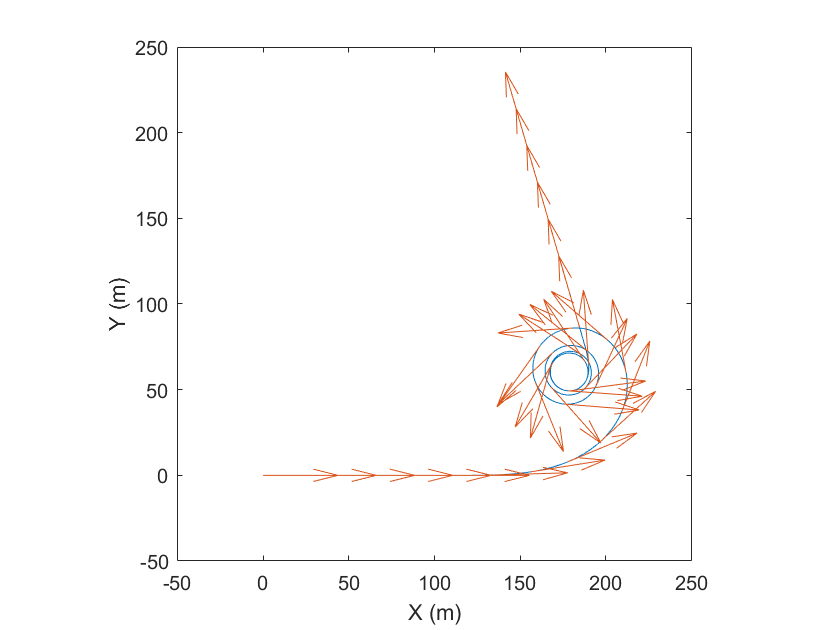

% Single-Track Model
a11 = -((C_alpha_R+C_alpha_F)/(m*v_fishhook));
a12 = (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_fishhook^2))-1;
a21 = ((C_alpha_R*b)-(C_alpha_F*a))/(Iz);
a22 = -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_fishhook);
b1 = (C_alpha_F)/(m*v_fishhook);
b2 = (C_alpha_F*a)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];
% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:35000
    X_dot(:,t) = A*X(:,t)+B*u_fishhook(t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-50,250])
ylim([-50,250])
pbaspect([1 1 1])

**Part B**

% Table of C_alpha vs F_z
C_alpha = [848 972 1088 1195 1292 1381 1461 1531 1593 1645 1689 1723 1748];
F_z = [2200 2600 3000 3400 3800 4200 4600 5000 5400 5800 6200 6600 7000];
% Calculate a and b
F = [F_z' (F_z.^2)'];
C = C_alpha';
ab = linsolve(F,C);
Ca = ab(1)

Ca = 0.4474

Cb = ab(2)

Cb = -2.8236e-05

% Static load
S_fl = 0.5*0.6*m*9.81;
S_fr = 0.5*0.6*m*9.81;
S_rl = 0.5*0.4*m*9.81;
S_rr = 0.5*0.4*m*9.81;

1. Step Maneuver

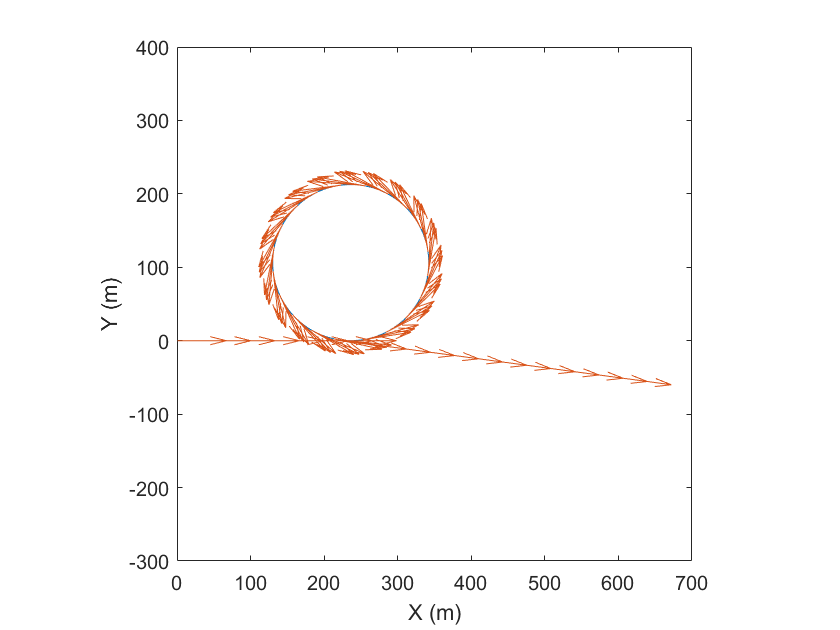

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:80000
    a_y(t) = v_step*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    C_alpha_fl = (Ca*Fz_fl + Cb*Fz_fl^2)*(180/pi);
    C_alpha_fr = (Ca*Fz_fr + Cb*Fz_fr^2)*(180/pi);
    C_alpha_rl = (Ca*Fz_rl + Cb*Fz_rl^2)*(180/pi);
    C_alpha_rr = (Ca*Fz_rr + Cb*Fz_rr^2)*(180/pi);
    C_alpha_F = C_alpha_fl+C_alpha_fr;
    C_alpha_R = C_alpha_rl+C_alpha_rr;
    A = [-((C_alpha_R+C_alpha_F)/(m*v_step)) (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_step^2))-1;
         ((C_alpha_R*b)-(C_alpha_F*a))/(Iz)  -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_step)];
    B = [(C_alpha_F)/(m*v_step);
         (C_alpha_F*a)/(Iz)];
    X_dot(:,t) = A*X(:,t)+B*u_step(t);
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,700])
ylim([-300,400])
pbaspect([1 1 1])

2(a). Fishhook Maneuver without Load Transfer

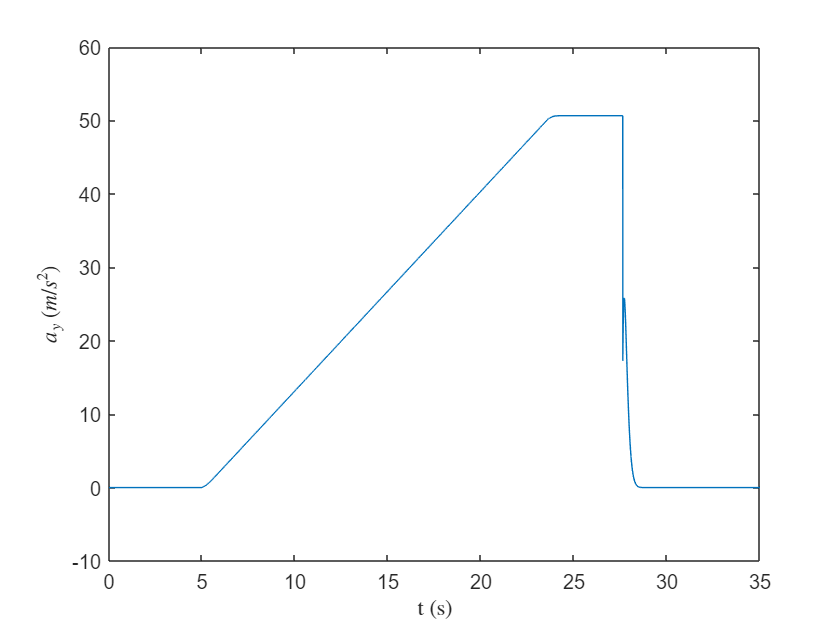

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl;
    Fz_fr = S_fr;
    Fz_rl = S_rl;
    Fz_rr = S_rr;
    C_alpha_fl = (Ca*Fz_fl + Cb*Fz_fl^2)*(180/pi);
    C_alpha_fr = (Ca*Fz_fr + Cb*Fz_fr^2)*(180/pi);
    C_alpha_rl = (Ca*Fz_rl + Cb*Fz_rl^2)*(180/pi);
    C_alpha_rr = (Ca*Fz_rr + Cb*Fz_rr^2)*(180/pi);
    C_alpha_F = C_alpha_fl+C_alpha_fr;
    C_alpha_R = C_alpha_rl+C_alpha_rr;
    A = [-((C_alpha_R+C_alpha_F)/(m*v_fishhook)) (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_fishhook^2))-1;
         ((C_alpha_R*b)-(C_alpha_F*a))/(Iz)  -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_fishhook)];
    B = [(C_alpha_F)/(m*v_fishhook);
         (C_alpha_F*a)/(Iz)];
    X_dot(:,t) = A*X(:,t)+B*u_fishhook(t);
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t=0:35000;
plot(t/1000,[0 a_y])
xlabel("t (s)",'interpreter','latex')
ylabel("$a_y$ $(m/s^2)$",'interpreter','latex')

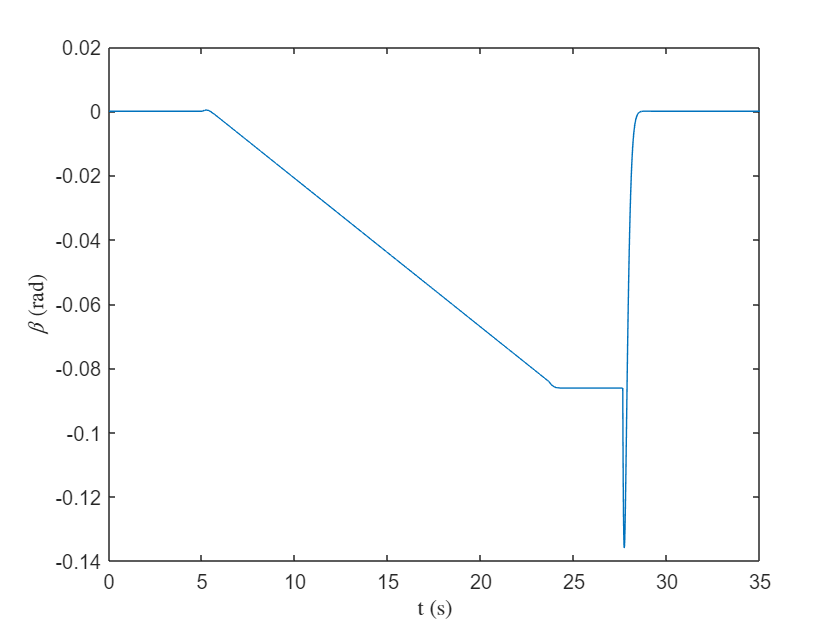

t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

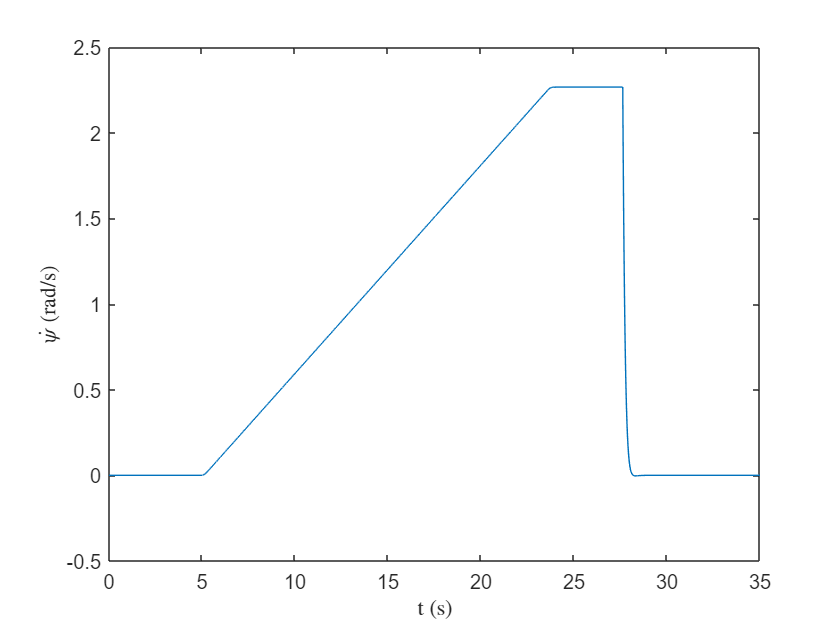

t=0:35000;
plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

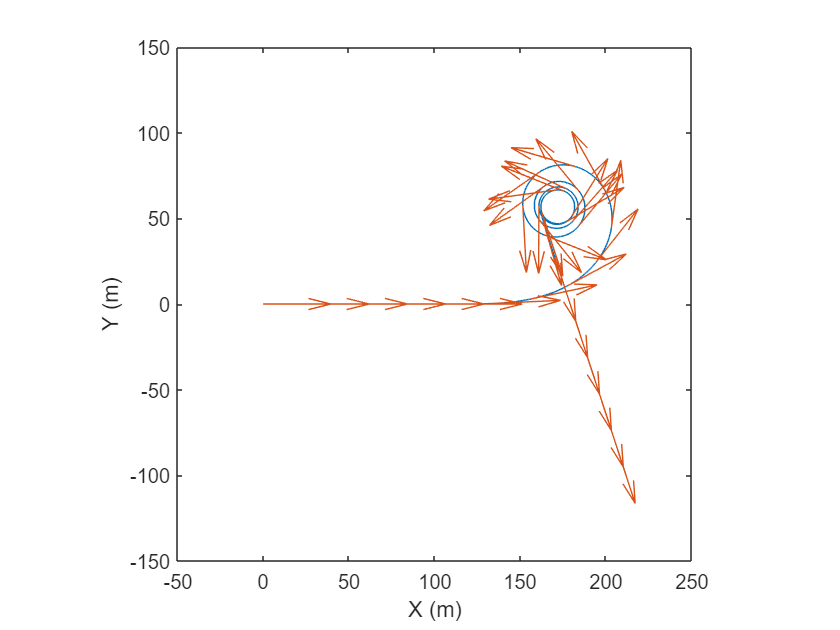

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-50,250])
ylim([-150,150])
pbaspect([1 1 1])

2(b). Fishhook Maneuver with Load Transfer

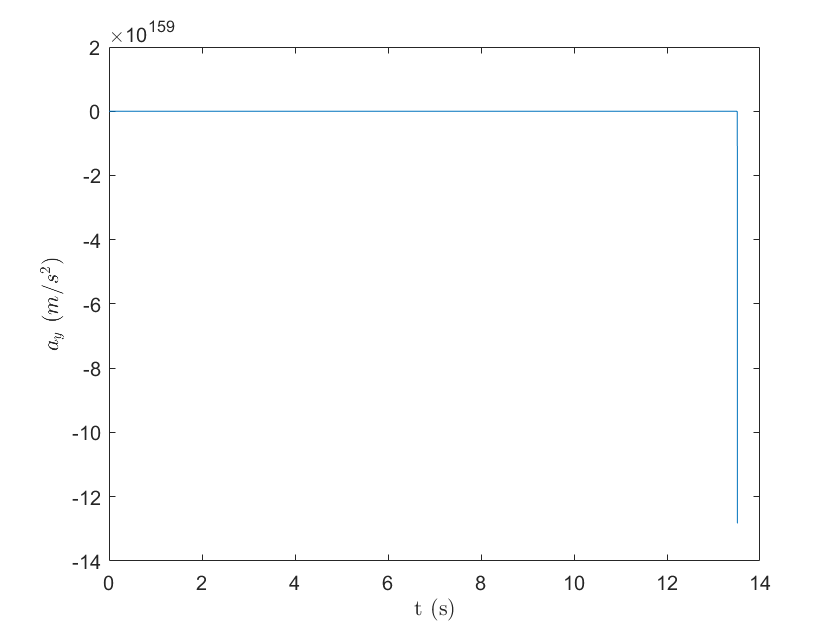

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    C_alpha_fl = (Ca*Fz_fl + Cb*Fz_fl^2)*(180/pi);
    C_alpha_fr = (Ca*Fz_fr + Cb*Fz_fr^2)*(180/pi);
    C_alpha_rl = (Ca*Fz_rl + Cb*Fz_rl^2)*(180/pi);
    C_alpha_rr = (Ca*Fz_rr + Cb*Fz_rr^2)*(180/pi);
    C_alpha_F = C_alpha_fl+C_alpha_fr;
    C_alpha_R = C_alpha_rl+C_alpha_rr;
    A = [-((C_alpha_R+C_alpha_F)/(m*v_fishhook)) (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_fishhook^2))-1;
         ((C_alpha_R*b)-(C_alpha_F*a))/(Iz)  -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_fishhook)];
    B = [(C_alpha_F)/(m*v_fishhook);
         (C_alpha_F*a)/(Iz)];
    X_dot(:,t) = A*X(:,t)+B*u_fishhook(t);
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t=0:35000;
plot(t/1000,[0 a_y])
xlabel("t (s)",'interpreter','latex')
ylabel("$a_y$ $(m/s^2)$",'interpreter','latex')

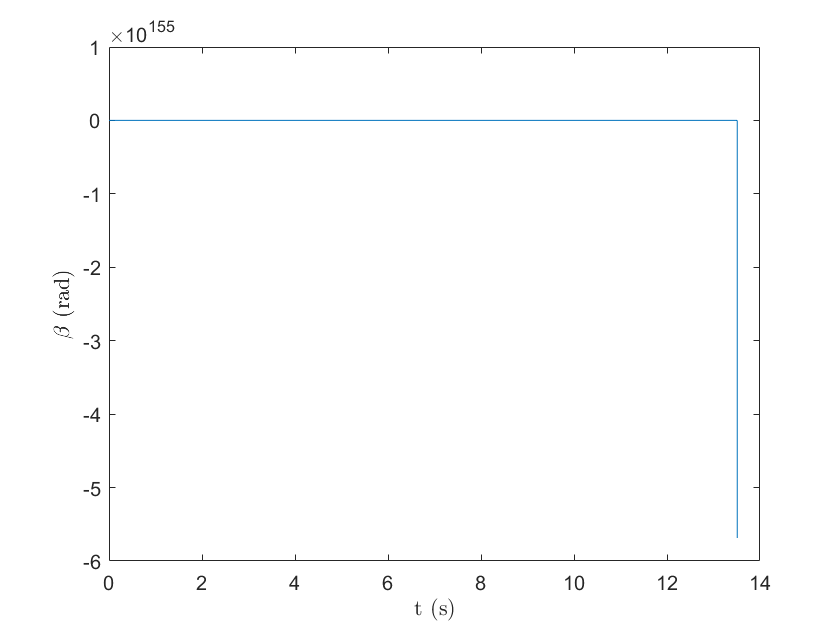

t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

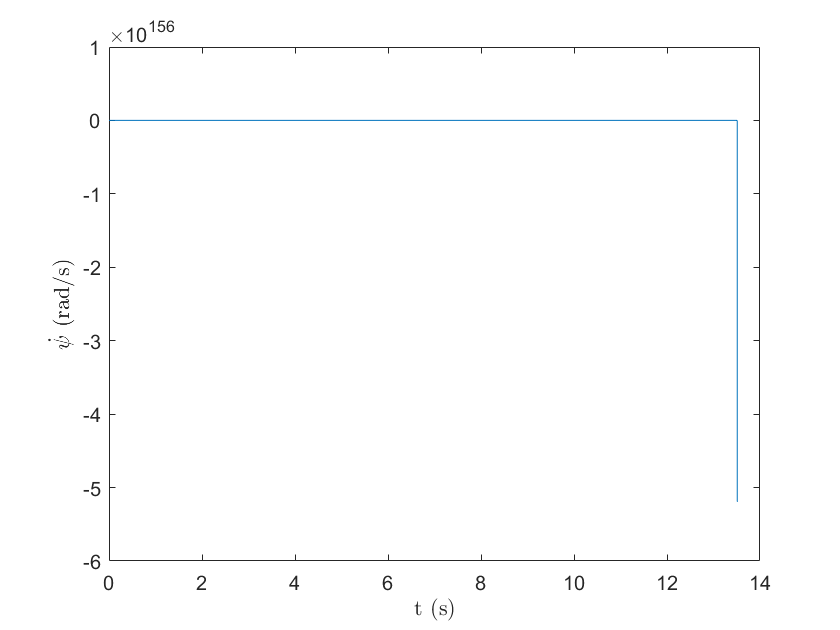

t=0:35000;
plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

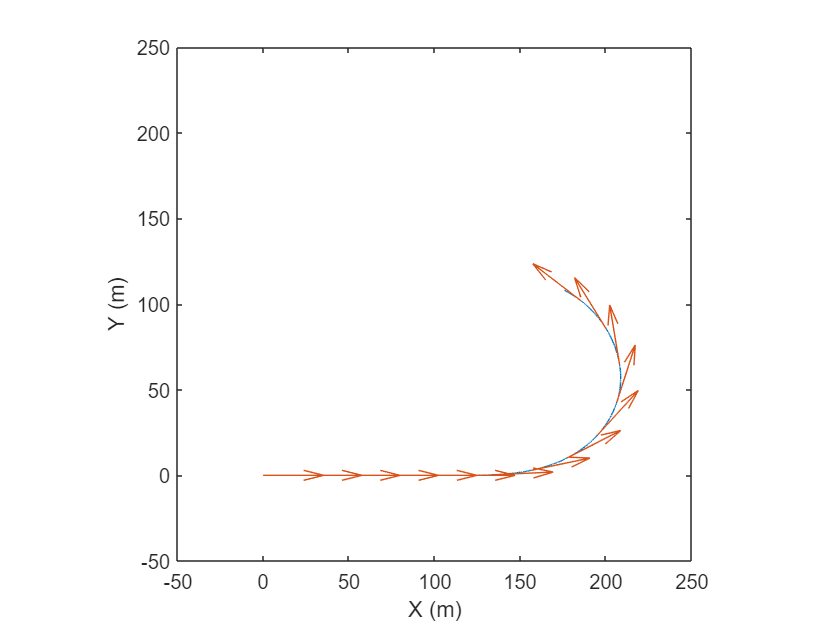

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-50,250])
ylim([-50,250])
pbaspect([1 1 1])

### Problem 2

In problem 1, the bicycle model was simulated assuming a linear tire model for a given load (of course, it is nonlinear model with respect to Fz). For this part, a non-linear tire model (nonlintire.m) is being provided to you. This tire model accepts an argument in the format ($\alpha ,F_z ,v$) where $\alpha$ is the slip angle, $F_z$ is the normal load, and $v$ is the longitudinal velocity of the wheel center, and returns a lateral force, $F_y$.

The given nonlinear tire model produces forces according to the non‐adapted ISO system, i.e., assuming negative cornering stiffness. However, our models are derived assuming positive cornering stiffness, i.e., positive slip angles correspond to positive forces. Therefore, you have to make the tire model compliant with your model.

**Part A:**

Using this non-linear tire model, for each maneuver, simulate the states of the bicycle model and determine the position of CG as well as the direction of the velocity vector in the inertial coordinate frame. Provide plots for the states as well as the trajectory of CG and direction of velocity vector – i.e., total 6 plots

**Part B:**

1. Calculate the Understeer Gradient (UG) of fishhook maneuver and step input without load transfer.

2. From the Fishhook maneuver, determine the sublimit Understeer Gradient (UG) with load transfer. Comment on the limit behavior.

3. Now assume a roll stiffness distribution of 70% rear 30% front and perform the same analysis as in section 2 of Part B. Comment on the results.

**NOTE:** In your report, clearly mention your approach, the equations used, and your observations along with the plots of your result. Attach your MATLAB code in the appendix of the report for reference.

### Solution 2

**Part A**

1(a). Step Maneuver without Load Transfer

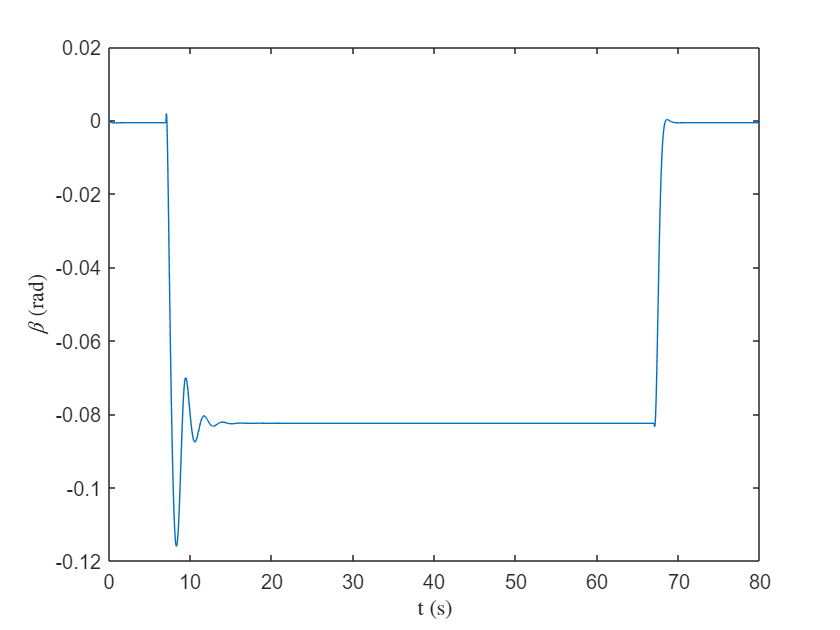

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:80000
    a_y = v_step*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y*h)/w;
    dW_r = 0.4*(m*a_y*h)/w;
    Fz_fl = S_fl;
    Fz_fr = S_fr;
    Fz_rl = S_rl;
    Fz_rr = S_rr;
    alpha_f = u_step(t) - (X(2,t)*a)/v_step - X(1,t);
    alpha_r = (X(2,t)*b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:80000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

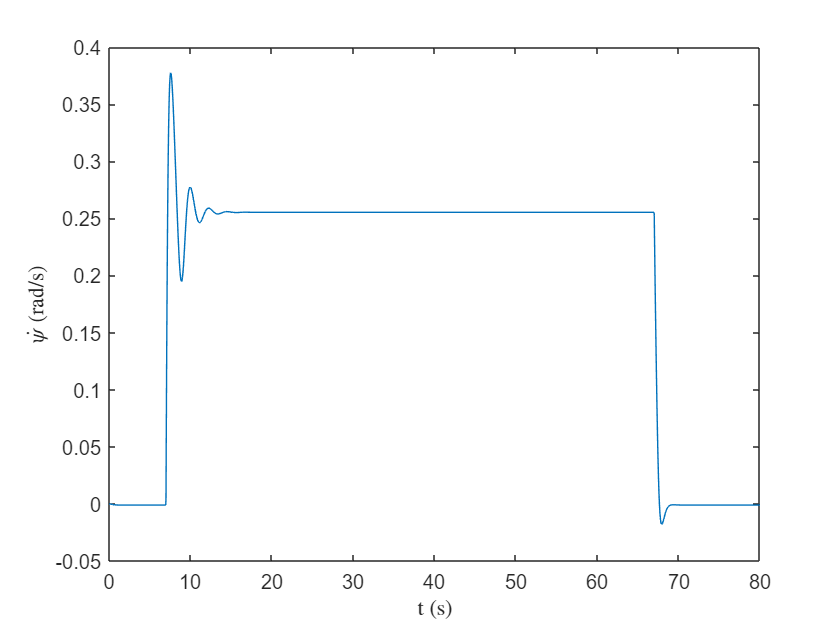

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

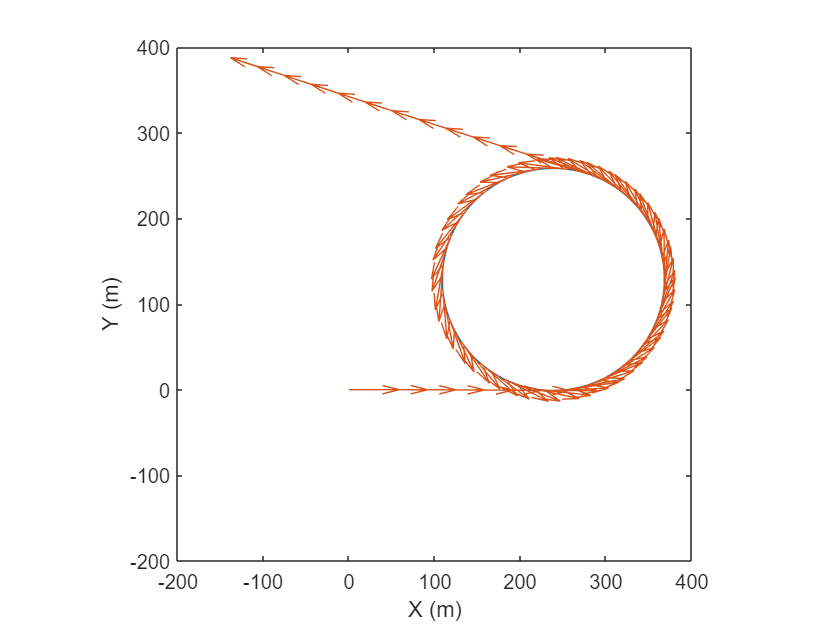

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([-200,400])
ylim([-200,400])
pbaspect([1 1 1])

1(b). Step Maneuver with Load Transfer

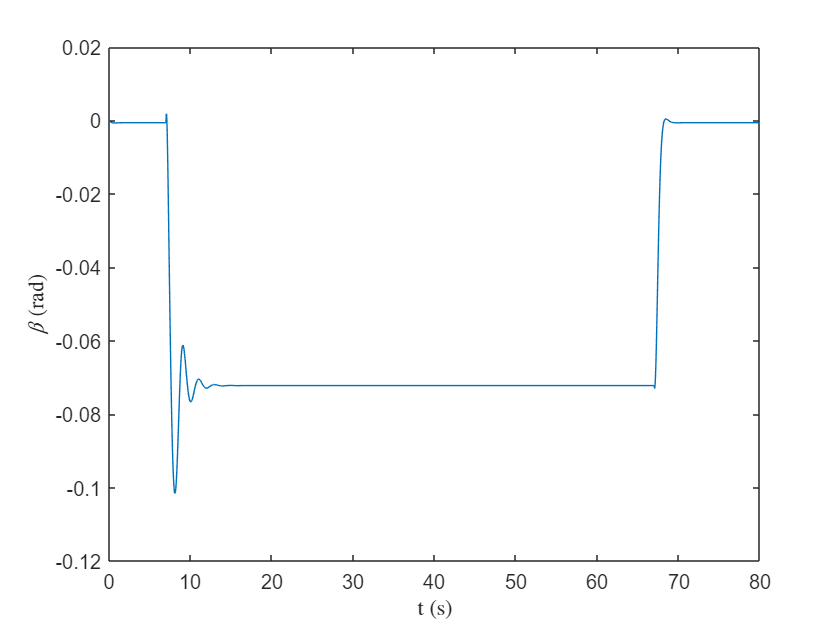

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:80000
    a_y = v_step*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y*h)/w;
    dW_r = 0.4*(m*a_y*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_step(t) - (X(2,t)*a)/v_step - X(1,t);
    alpha_r = (X(2,t)*b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plots
t=0:80000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

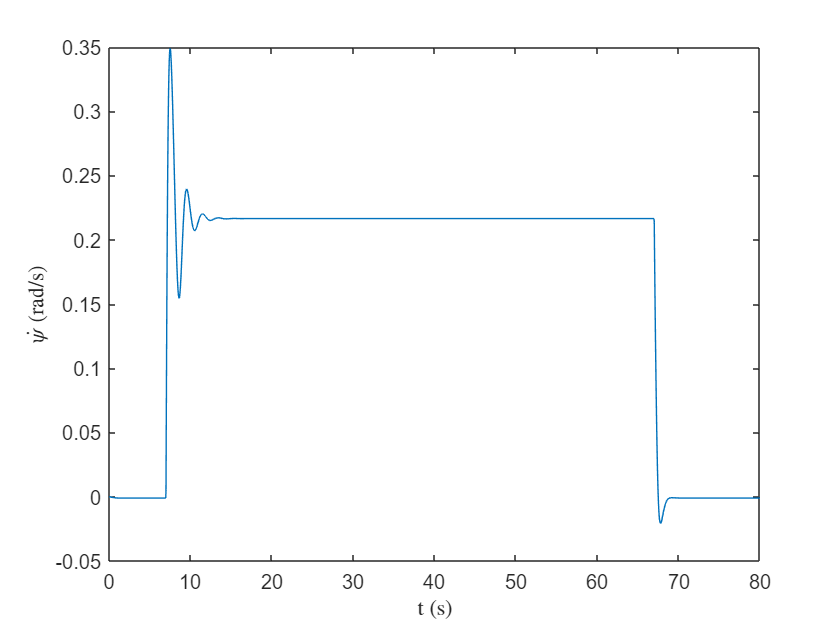

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

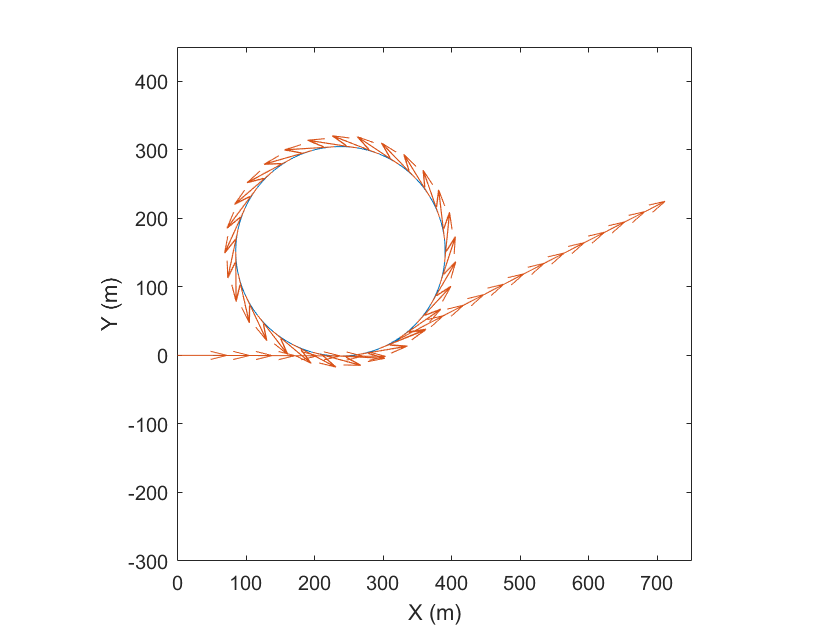

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,750])
ylim([-300,450])
pbaspect([1 1 1])

2(a). Fishhook Maneuver without Load Transfer

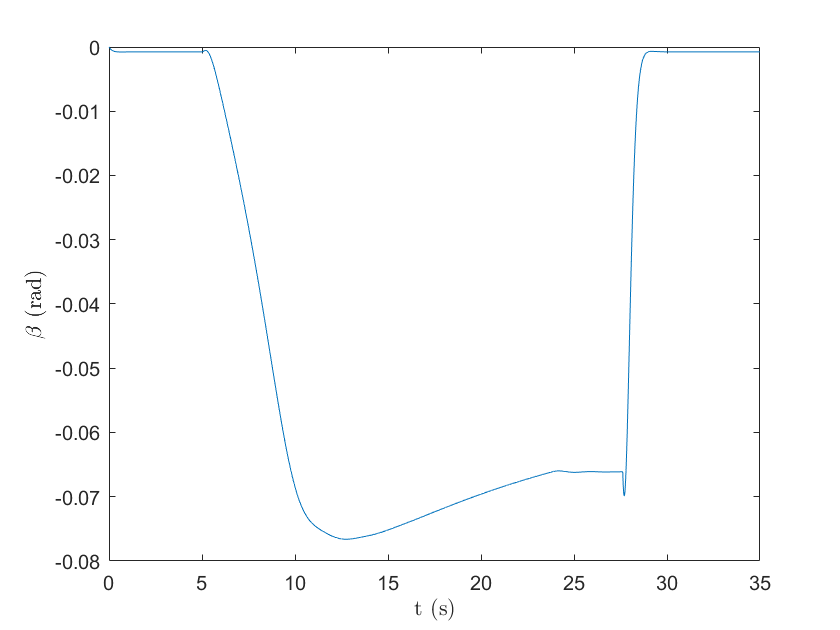

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:35000
    a_y = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y*h)/w;
    dW_r = 0.4*(m*a_y*h)/w;
    Fz_fl = S_fl;
    Fz_fr = S_fr;
    Fz_rl = S_rl;
    Fz_rr = S_rr;
    alpha_f = u_fishhook(t) - (X(2,t)*a)/v_fishhook - X(1,t);
    alpha_r = (X(2,t)*b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

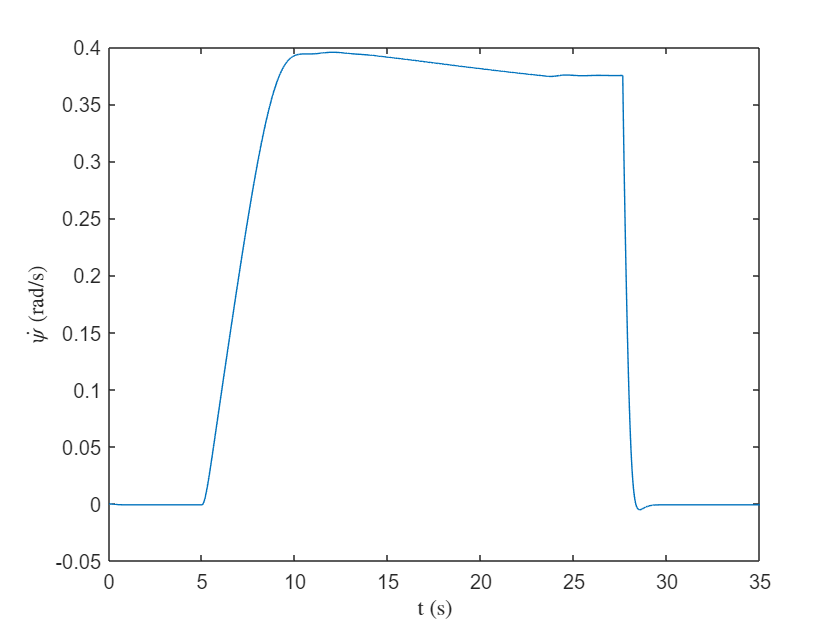

t=0:35000;
plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

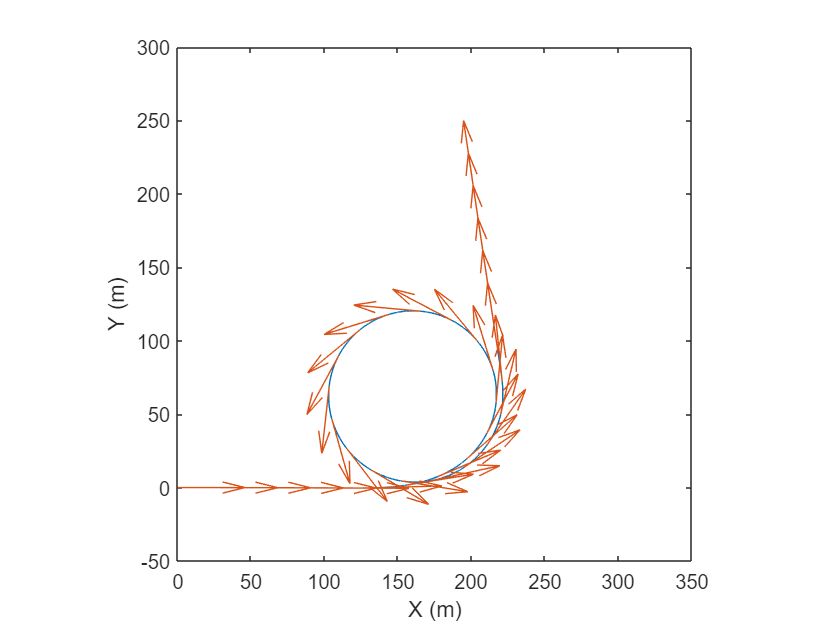

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,350])
ylim([-50,300])
pbaspect([1 1 1])

2(b). Fishhook Maneuver with Load Transfer

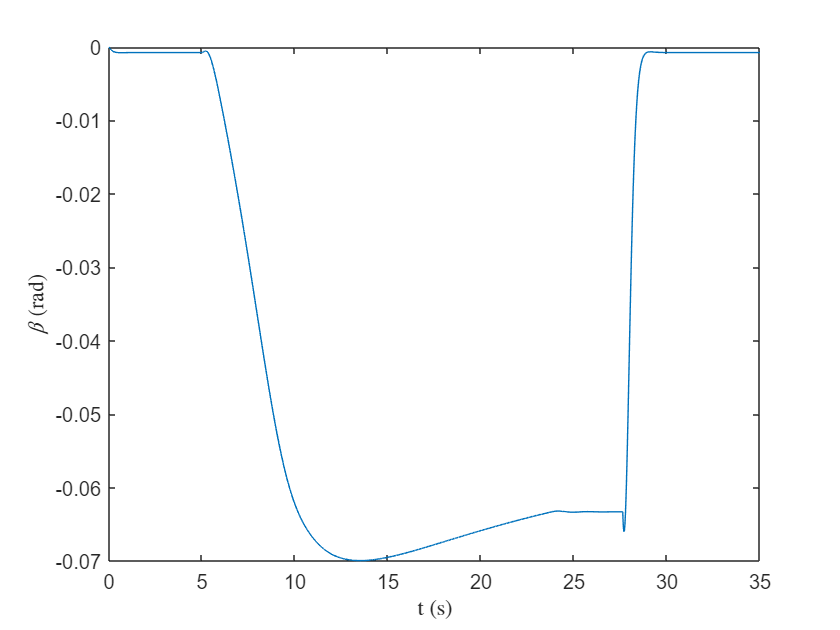

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:35000
    a_y = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y*h)/w;
    dW_r = 0.4*(m*a_y*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f = u_fishhook(t) - (X(2,t)*a)/v_fishhook - X(1,t);
    alpha_r = (X(2,t)*b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t=0:35000;
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

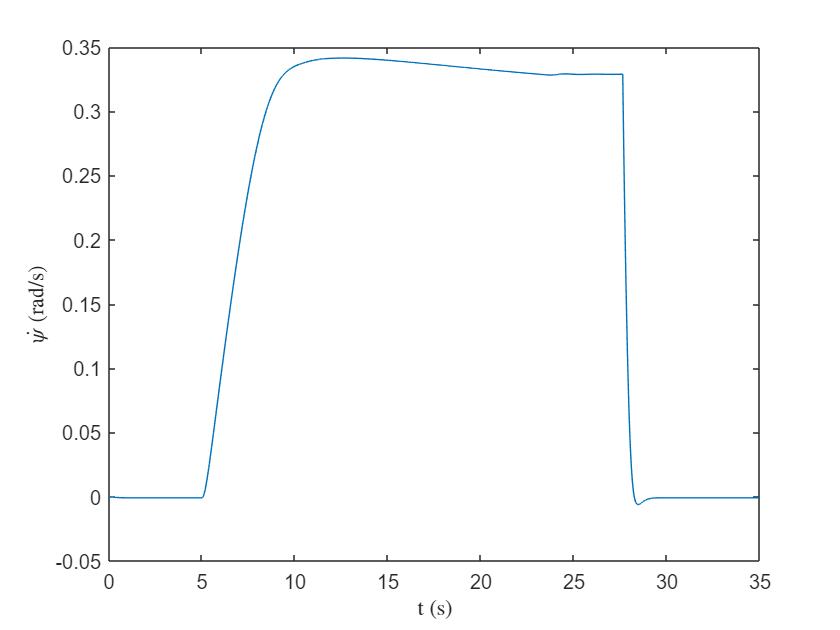

t=0:35000;
plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

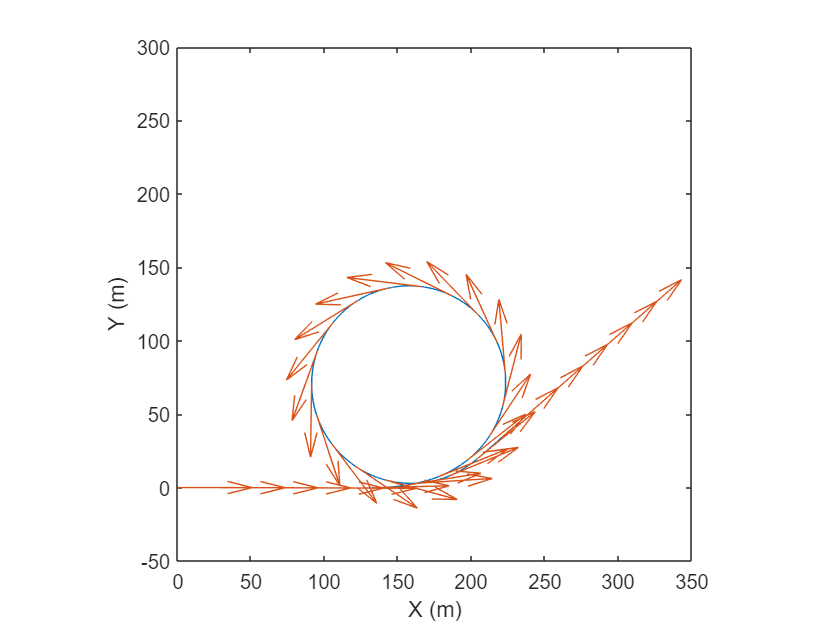

plot(Px(1:end-1),Py(1:end-1))
hold on;
quiver(Px(1:1000:end-1000),Py(1:1000:end-1000),Vx(1:1000:end),Vy(1:1000:end))
hold off;
xlabel("X (m)")
ylabel("Y (m)")
xlim([0,350])
ylim([-50,300])
pbaspect([1 1 1])

**Part B:**

1. Calculate the Understeer Gradient (UG) of fishhook maneuver and step input without load transfer.

(a) Step Maneuver

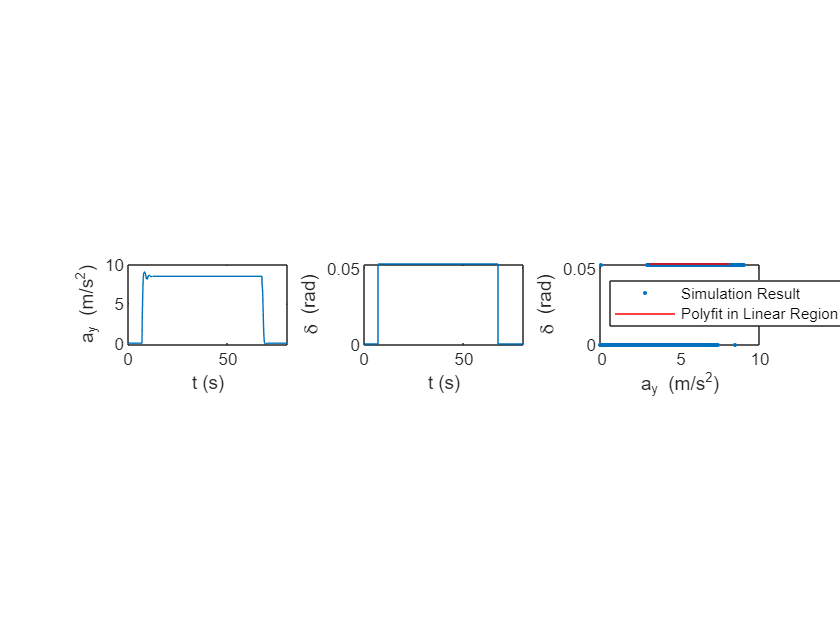

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
% Simulation at each millisecond
for t=1:80000
    a_y(t) = v_step*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl;
    Fz_fr = S_fr;
    Fz_rl = S_rl;
    Fz_rr = S_rr;
    alpha_f(t) = u_step(t) - (X(2,t)*a)/v_step - X(1,t);
    alpha_r(t) = (X(2,t)*b)/v_step - X(1,t);
    Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_step);
    Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_step);
    Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_step);
    Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_step);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_step) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_step*cos(Psi(t)+Beta(t));
    Vy(t) = v_step*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t = 1:80000;
figure()
subplot(1,3,1)
plot(t/1000,a_y)
xlabel("t (s)")
ylabel("a_y (m/s^2)")
pbaspect([2 1 1])
subplot(1,3,2)
plot(t/1000,u_step)
xlabel("t (s)")
ylabel("\delta (rad)")
pbaspect([2 1 1])
subplot(1,3,3)
plot(a_y,u_step,'.')
hold on;
UG_poly = polyfit(a_y(7100:7600), u_step(7100:7600), 1);
plot(a_y(7100:7600),polyval(UG_poly,a_y(7100:7600)),'r');
hold off;
xlabel("a_y (m/s^2)")
ylabel("\delta (rad)")
legend("Simulation Result","Polyfit in Linear Region",'Location','NW')
pbaspect([2 1 1])

UG = (alpha_f(55000)-alpha_r(55000))/a_y(55000);
UG = polyder(UG_poly);
fprintf("UG for step maneuver with non-linear tire model, without load transfer is %.4f rad-s^2/m", UG);

UG for step maneuver with non-linear tire model, without load transfer is 0.0000 rad-s^2/m

(b) Fishhook Maneuver

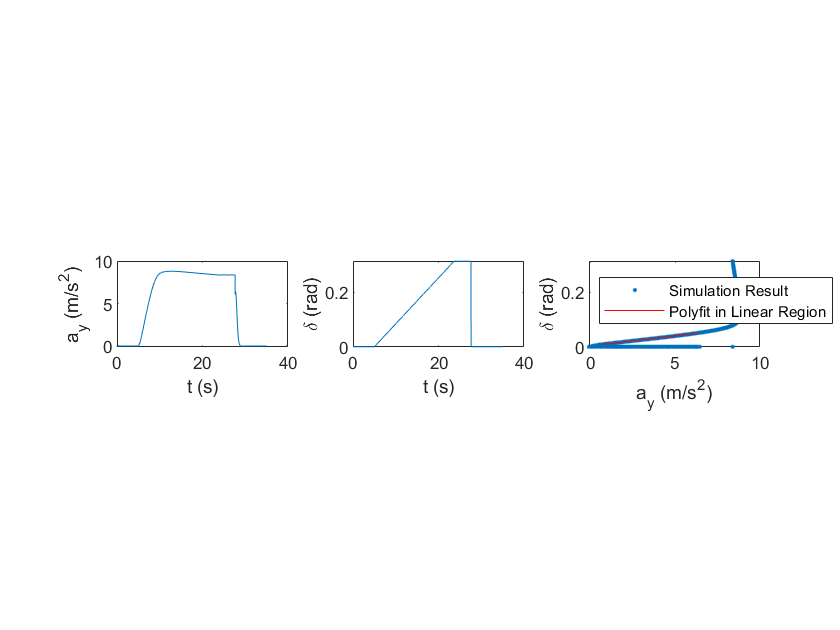

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl;
    Fz_fr = S_fr;
    Fz_rl = S_rl;
    Fz_rr = S_rr;
    alpha_f = u_fishhook(t) - (X(2,t)*a)/v_fishhook - X(1,t);
    alpha_r = (X(2,t)*b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f, Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f, Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r, Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r, Fz_rr, v_fishhook);
    Fy_f = Fy_fl+Fy_fr;
    Fy_r = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f+Fy_r)/(m*v_fishhook) - X(2,t);
                  (Fy_f*a-Fy_r*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t = 1:35000;
figure()
subplot(1,3,1)
plot(t/1000,a_y)
xlabel("t (s)")
ylabel("a_y (m/s^2)")
pbaspect([2 1 1])
subplot(1,3,2)
plot(t/1000,u_fishhook)
xlabel("t (s)")
ylabel("\delta (rad)")
pbaspect([2 1 1])
subplot(1,3,3)
plot(a_y,u_fishhook,'.')
hold on;
UG_poly = polyfit(a_y(5500:8000), u_fishhook(5500:8000), 1);
plot(a_y(5500:8000),polyval(UG_poly,a_y(5500:8000)),'r');
hold off;
xlabel("a_y (m/s^2)")
ylabel("\delta (rad)")
legend("Simulation Result","Polyfit in Linear Region",'Location','NW')
pbaspect([2 1 1])

UG = polyder(UG_poly) - l/(v_fishhook^2);
fprintf("UG for fishhook maneuver with non-linear tire model, without load transfer is %.4f rad-s^2/m", UG);

UG for fishhook maneuver with non-linear tire model, without load transfer is 0.0018 rad-s^2/m

2. From the Fishhook maneuver, determine the sublimit Understeer Gradient (UG) with load transfer. Comment on the limit behavior.

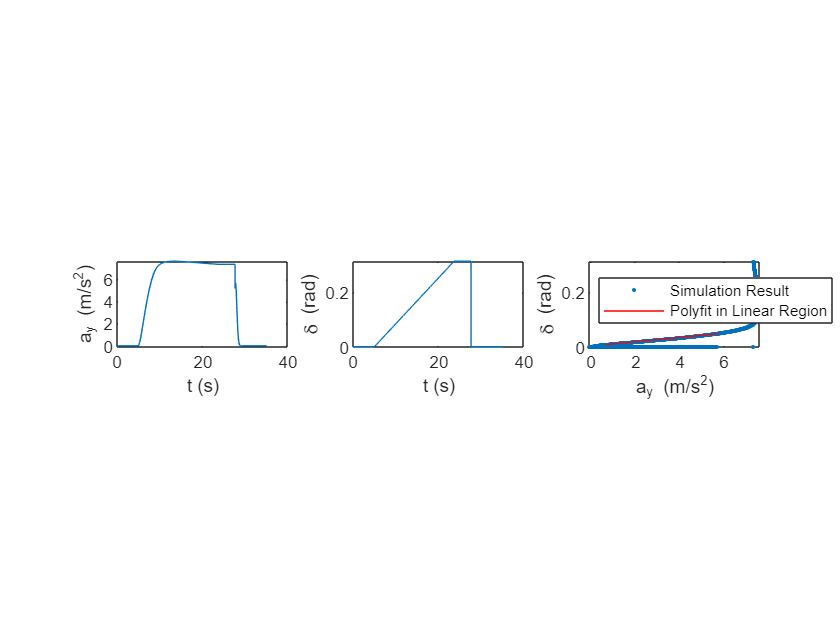

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
alpha_f = [];
alpha_r = [];
Fy_f = [];
Fy_r = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.6*(m*a_y(t)*h)/w;
    dW_r = 0.4*(m*a_y(t)*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f(t) = u_fishhook(t) - (X(2,t)*a)/v_fishhook - X(1,t);
    alpha_r(t) = (X(2,t)*b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_fishhook);
    Fy_f(t) = Fy_fl+Fy_fr;
    Fy_r(t) = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f(t)+Fy_r(t))/(m*v_fishhook) - X(2,t);
                  (Fy_f(t)*a-Fy_r(t)*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t = 1:35000;
figure()
subplot(1,3,1)
plot(t/1000,a_y)
xlabel("t (s)")
ylabel("a_y (m/s^2)")
pbaspect([2 1 1])
subplot(1,3,2)
plot(t/1000,u_fishhook)
xlabel("t (s)")
ylabel("\delta (rad)")
pbaspect([2 1 1])
subplot(1,3,3)
plot(a_y,u_fishhook,'.')
hold on;
UG_poly = polyfit(a_y(5500:8000), u_fishhook(5500:8000), 1);
plot(a_y(5500:8000),polyval(UG_poly,a_y(5500:8000)),'r');
hold off;
xlabel("a_y (m/s^2)")
ylabel("\delta (rad)")
legend("Simulation Result","Polyfit in Linear Region",'Location','NW')
pbaspect([2 1 1])

UG = polyder(UG_poly) - l/(v_fishhook^2);
fprintf("UG for fishhook maneuver with non-linear tire model, with load transfer is %.4f rad-s^2/m", UG);

UG for fishhook maneuver with non-linear tire model, with load transfer is 0.0025 rad-s^2/m

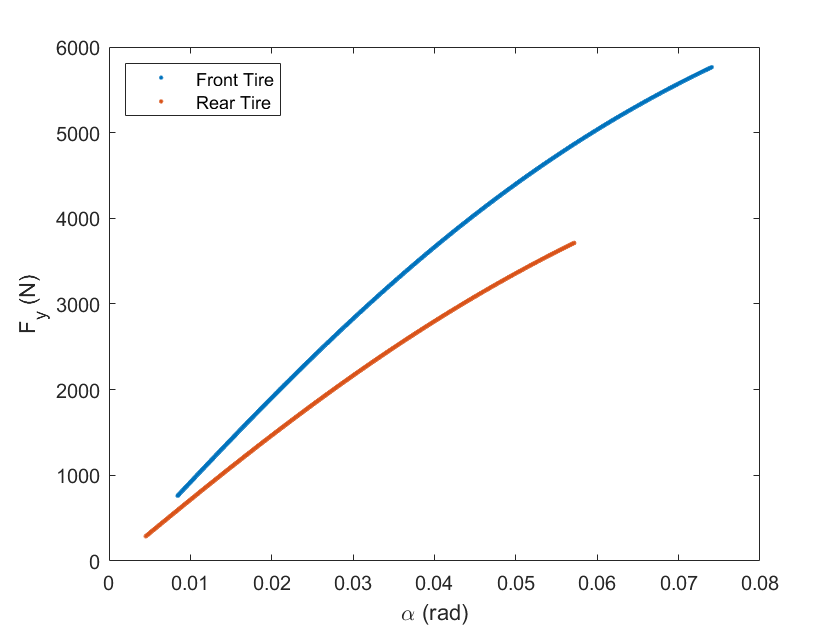

figure()
plot(alpha_f(5500:8000),Fy_f(5500:8000),'.')
hold on;
plot(alpha_r(5500:8000),Fy_r(5500:8000),'.')
hold off;
xlabel("\alpha (rad)")
ylabel("F_y (N)")
legend("Front Tire","Rear Tire",'Location','NW')

3. Now assume a roll stiffness distribution of 70% rear 30% front and perform the same analysis as in section 2 of Part B. Comment on the results.

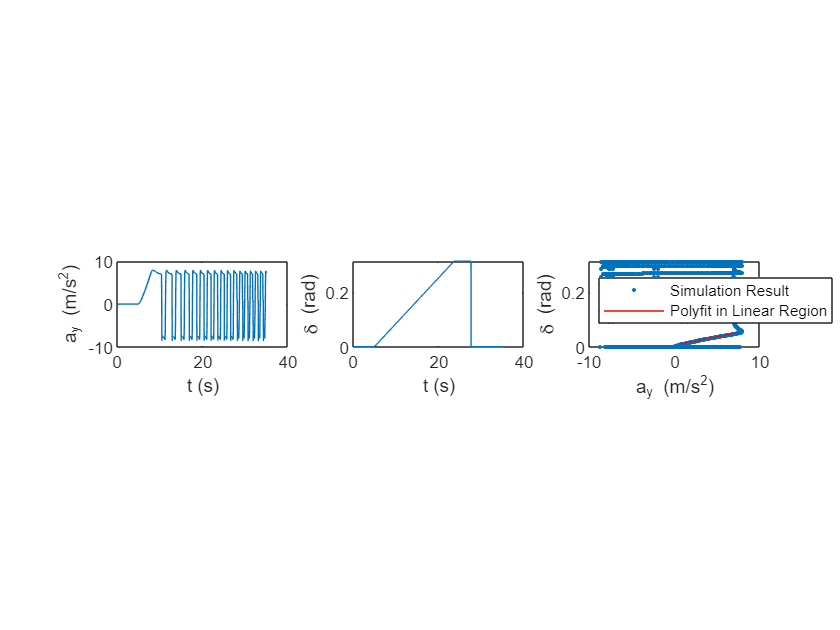

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
Psi = [];
Psi(1) = 0;
Beta = [];
B_dot = 0;
Vx = [];
Vy = [];
Px = [];
Px(1) = 0;
Py = [];
Py(1) = 0;
a_y = [];
alpha_f = [];
alpha_r = [];
Fy_f = [];
Fy_r = [];
% Simulation at each millisecond
for t=1:35000
    a_y(t) = v_fishhook*(B_dot+X(2,t));
    dW_f = 0.3*(m*a_y(t)*h)/w;
    dW_r = 0.7*(m*a_y(t)*h)/w;
    Fz_fl = S_fl - dW_f;
    Fz_fr = S_fr + dW_f;
    Fz_rl = S_rl - dW_r;
    Fz_rr = S_rr + dW_r;
    alpha_f(t) = u_fishhook(t) - (X(2,t)*a)/v_fishhook - X(1,t);
    alpha_r(t) = (X(2,t)*b)/v_fishhook - X(1,t);
    Fy_fl = -nonlintire(alpha_f(t), Fz_fl, v_fishhook);
    Fy_fr = -nonlintire(alpha_f(t), Fz_fr, v_fishhook);
    Fy_rl = -nonlintire(alpha_r(t), Fz_rl, v_fishhook);
    Fy_rr = -nonlintire(alpha_r(t), Fz_rr, v_fishhook);
    Fy_f(t) = Fy_fl+Fy_fr;
    Fy_r(t) = Fy_rl+Fy_rr;
    X_dot(:,t) = [(Fy_f(t)+Fy_r(t))/(m*v_fishhook) - X(2,t);
                  (Fy_f(t)*a-Fy_r(t)*b)/(Iz)];
    B_dot = X_dot(1,t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
    Beta(t) = X(1,t);
    Psi(t+1) = Psi(t) + X(2,t)*dt;
    Vx(t) = v_fishhook*cos(Psi(t)+Beta(t));
    Vy(t) = v_fishhook*sin(Psi(t)+Beta(t));
    Px(t+1) = Px(t) + Vx(t)*dt;
    Py(t+1) = Py(t) + Vy(t)*dt;
end
% Plot
t = 1:35000;
figure()
subplot(1,3,1)
plot(t/1000,a_y)
xlabel("t (s)")
ylabel("a_y (m/s^2)")
pbaspect([2 1 1])
subplot(1,3,2)
plot(t/1000,u_fishhook)
xlabel("t (s)")
ylabel("\delta (rad)")
pbaspect([2 1 1])
subplot(1,3,3)
plot(a_y,u_fishhook,'.')
hold on;
UG_poly = polyfit(a_y(5500:8000), u_fishhook(5500:8000), 1);
plot(a_y(5500:8000),polyval(UG_poly,a_y(5500:8000)),'r');
hold off;
xlabel("a_y (m/s^2)")
ylabel("\delta (rad)")
legend("Simulation Result","Polyfit in Linear Region",'Location','NW')
pbaspect([2 1 1])

UG = polyder(UG_poly) - l/(v_fishhook^2);
fprintf("UG for fishhook maneuver with non-linear tire model, with load transfer is %.4f rad-s^2/m", UG);

UG for fishhook maneuver with non-linear tire model, with load transfer is 0.0007 rad-s^2/m

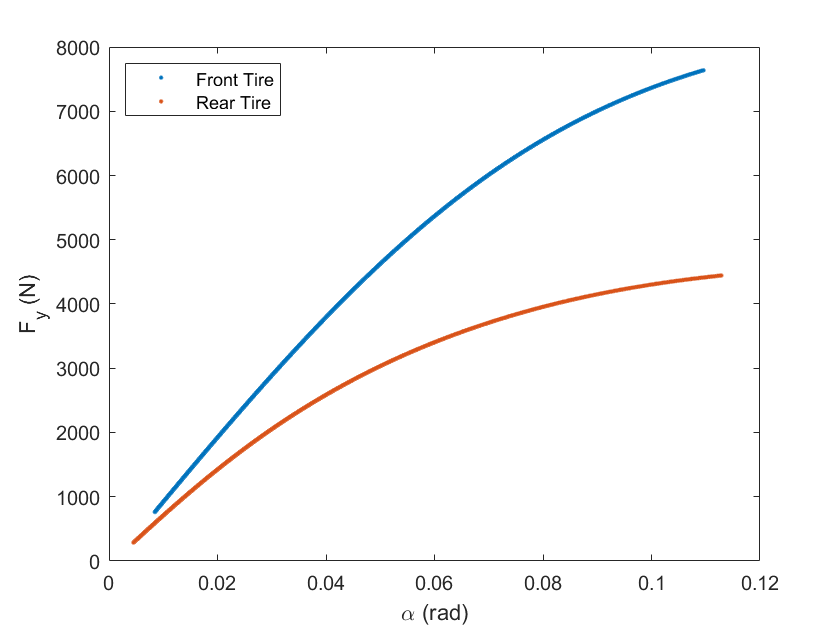

figure()
plot(alpha_f(5500:8000),Fy_f(5500:8000),'.')
hold on;
plot(alpha_r(5500:8000),Fy_r(5500:8000),'.')
hold off;
xlabel("\alpha (rad)")
ylabel("F_y (N)")
legend("Front Tire","Rear Tire",'Location','NW')